# 电子信息工程建模与仿真大作业

**姓名：李锦川    班级：119070201    学号：11907980422**

**一、某线性系统的闭路传递函数如下，请画出系统的波特图。**


$$G\left(s\right)=\frac{80s}{s\left(s+1\right)\left(s+10\right)\left(s+15\right)}$$


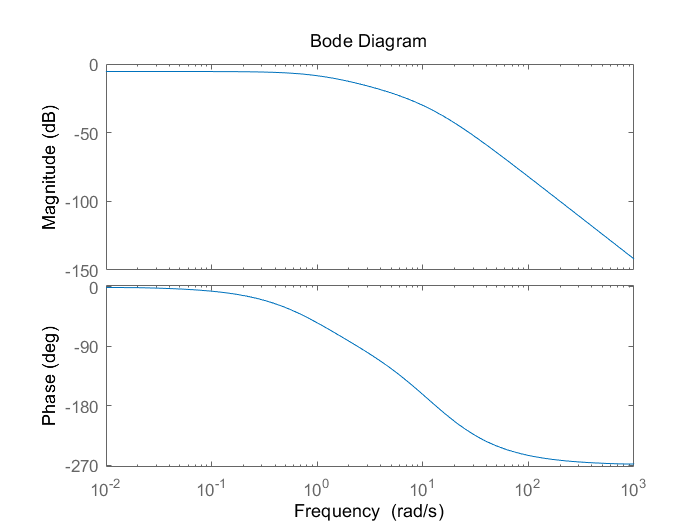

num=[80,0]; %设置num参数，来自于分子
den=conv(conv(conv([1 0],[1 1]),[1 10]),[1,15]); %参数取自于分母
bode(num,den)

**二、某系统的开环传递函数的形式为**


$$G\left(s\right)=\frac{50}{\left(s+10\right)}$$


*        1. 请画出该开环系统的波特图； *

*        2. 若该开环系统的-1 反馈构成一个闭环系统，请绘制闭环系统的奈硅斯特图，并判定闭环系统是否稳定？*

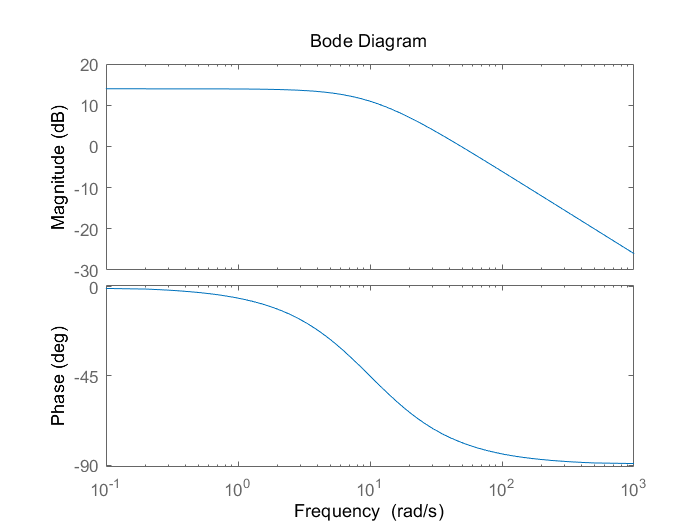

num=50;
den=[1,10];
bode(num,den)

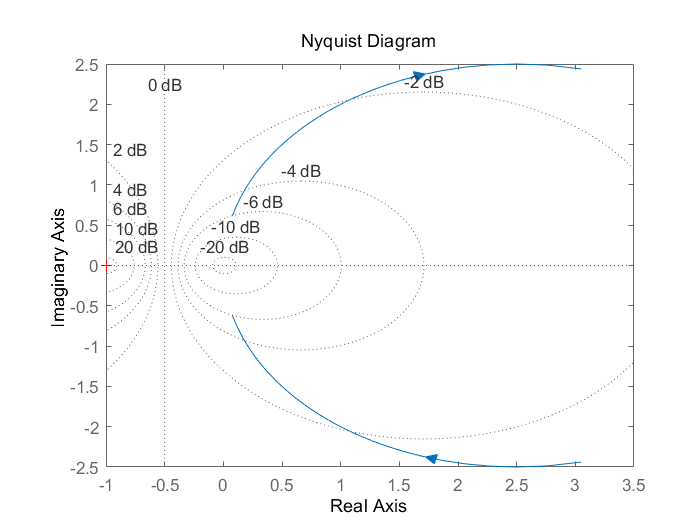

w=8:1:80;
num=50;
den=[1 10];
figure(1)
nyquist(num,den, w);
grid;

由图上可见，奈奎斯特轨迹永远不会包围$s=-1+j0$, 所以闭环系统是稳定的。

**三、 已知开环传递函数如下所示：**


$$H\left(s\right)=\frac{K\left(s+2\right)}{\left(s^2 +4s+3\right)}$$


*要求绘制该系统的闭环根轨迹，分析其稳定性， 井绘制出 K=55 时系统的闭环冲激响应。 *

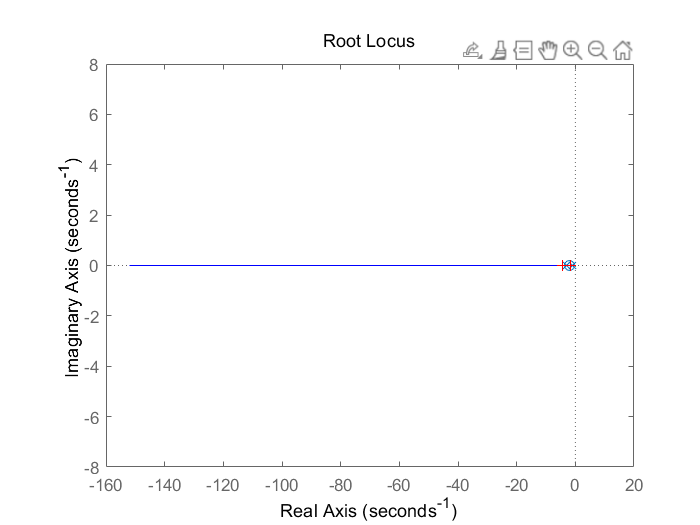

Select a point in the graphics window


selected_point = 0.3977 - 0.0794i

k = 1.9833

p =    -4.4000
   -1.5833


num=[1 2];
den=[1 4 3];
figure(1)
k=0:0.1:150;
rlocus(num,den,k)
title('Root Locus');
[k,p]=rlocfind(num,den)

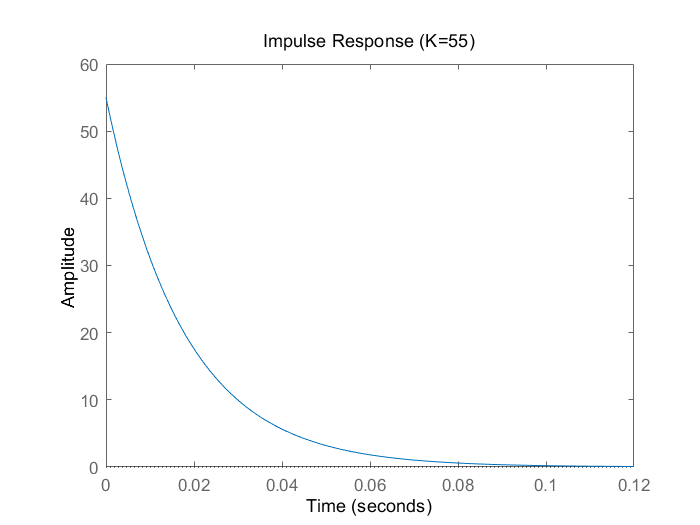

%检验系统的稳定性
figure(2)
k=55;
num1=k*[1 2];
den=[1 4 3];
[ num,den ]=cloop(num1,den,-1);
impulse(num,den)
title('Impulse Response (K=55)');

从图可以看出， 当K=55时闭环系统稳定。

**四、典型二阶系统如下所示**


$$G\left(s\right)=\frac{{\omega_n }^2 }{s^2 +2\zeta \omega_n s+{\omega_n }^2 }$$


*其中 *$\omega_n$*为自然频率（无阻尼振荡频率），*$\xi$* 为阻尼系数。要求绘制出当 *$\omega_n =6$,$\xi$*分别为 0.1,0.2,...1 时系统的单位冲激响应。*

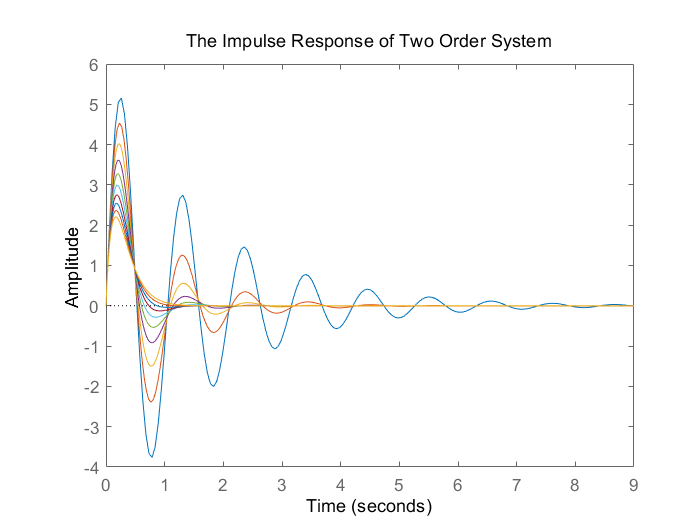

wn=6;
kosai=[0.1:0.1:1];
figure(1);clf
hold on
for i=kosai
    num=wn.^2;
    den=[1, 2*i*wn, wn.^2];
    %step(num,den)
    impulse(num,den)
end
title('The Impulse Response of Two Order System')